Companion software for "Volker Ziemann, *Hands-on Accelerator physics using MATLAB, CRCPress, 2019*" (https://www.crcpress.com/9781138589940)

# Phase space of a small-signal free-electron laser (Section 10.3)

Volker Ziemann, 211124, CC-BY-SA-4.0

**Important:** requires the elliptic package from [https://github.com/moiseevigor/elliptic](https://github.com/moiseevigor/elliptic) located in a subdirectory below the present one (for the fast evaluation of elliptic functions).

The dynamics of an electron moving in an undulator magnet and, at the same time, exposed to the field of an external laser can be described by a mathematical pendulum, given by Equation 10.30, which reads $\ddot\psi+\Omega^2\sin\psi=0$. Here $\eta=\dot\psi$ describes the energy difference with respect to the energy at which the electron motion and laser are synchronous, which is is encoded in the FEL resonance condition in Equation 10.28. Since the electron bunches are much longer than the laser wavelength, we can assume that the electrons are uniformly distributed in phase and follow these uniformly distributed electrons for some time and calculate where they are at the end of the FEL.

The intensity of the laser and the parameters of the undulator are encoded in the oscillation frequency $\Omega$ and is given in Equation 10.30. We set the duration of the FEL process to 1/10 of the full oscillation period and then define a range of starting phase $\phi$.

clear
addpath ./elliptic    
Omega=0.25  % Slider to set Omega

Omega = 0.2500

Ts=2*pi/Omega;
dt=0.1*Ts;   % time step
phi=-pi:2*pi/201:pi;

We define the separatrix, which separates the periodic from the non-periodic trajectories, and plot both its upper and the lower branch. Then we scale the axes and annotate the plot. 

separatrix=2*Omega*cos(0.5*phi);  % eq. 5.47
clf
plot(phi,separatrix,'k',phi,-separatrix,'k')
axis([-pi,pi,-0.85,0.85]); 
set(gca,'xtick',[-pi,-pi/2,0,pi/2,pi],'fontsize',14, ...
  'xticklabels',{'-\pi','-\pi/2','0','\pi/2','\pi'})
xlabel('\psi'); 
ylabel('$$\dot\psi$$','interpreter','latex')
hold on; 

Now we define a range of initial starting values for $\eta=\dot\psi$ and loop over the two values. Inside that loop we loop over the uniformly distributed starting phases of the electron that we mark with a green dot and use `pendulumtracker()`, defined in the Appendix, to find the final position after time `dt`, which we mark by a red dot. In this way we follow where each electron starts and ends it journey through the FEL.

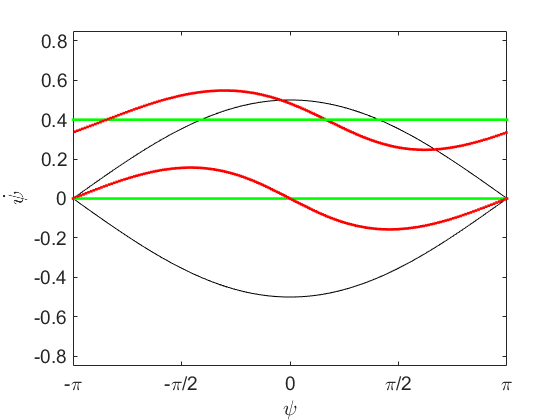

eta2=0.4; % Slider for the second value of eta
eta0=[0,eta2];
for m=1:length(eta0)
  for k=1:length(phi)
    plot(phi(k),eta0(m),'g.') 
    x=pendulumtracker([phi(k),eta0(m)],Omega,dt);
    plot(x(1),x(2),'r.')  
    pause(0.001)
  end
end

When looking very carefully it is possible to note that the final distribution of the electrons that start with $\eta=0$ is symmetric; half the electrons gains energy ($\dot\psi$ above the green line) and the other half  loses energy ($\dot\psi$below the green line), such that the net effect is zero. On the other hand, the final positions of the electrons that start with $\eta=\dot\psi=0.4$ show a slight imbalance between those that gain and those that lose energy.

#### Small-signal gain

In order to explore this imbalance we select a larger range of starting energies $\eta$ (green) and calculate the average value of $\eta$ at the final (red) positions, which will be proportional to the averaged energy loss of the electrons. Since energy is conserved this energy increases the energy of the laser and is therefore normally called `gain`. 

eta=-5.002:0.2:5;             % range of etas to explore
gain=zeros(1,length(eta));    

We initialize the figure so we can watch the points added as they are calculated.

figure; hold on
xlim([-5,5]); ylim([-7e-3,7e-3])
xlabel('\eta_0 = (\gamma_0-\gamma_r)/\gamma_r'); 
ylabel('<\eta_f> - \eta_0')

In the following loop we scan the range of `eta` and then over the starting phases phi. Inside these loops we use pendulumtracker() to move the electrons to their final position, where we use their energy, available as x(2), to contribute to the gain. Whenever the loop over the phases completes, we plot an asterisk with the initial `eta` as the horizontal coordinate and the `gain` as the vertical coordinate.

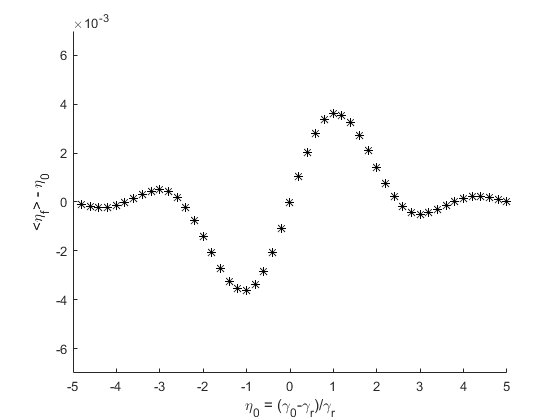

for m=1:length(eta)
  for k=1:length(phi)
    x=pendulumtracker([phi(k),eta(m)],Omega,dt);
    gain(m)=gain(m)+x(2);
  end
  gain(m)=eta(m)-gain(m)/length(phi);
  plot(eta(m),gain(m),'k*');
  pause(0.001);
end

This curve is known as the small-signal FEL gain curve, which can also be derived analytically with the result shown in Equation 10.31. 

## Appendix

The function` pendulumtracker()` receives the phase-space coordinates `x` at the start, the small-amplitude oscillation frequency `omega`, and the integration time `dt` as input and returns the phase-space coordinates `xout`. Internally, it integrates the equations of motion for a mathematical pendulum in closed form using Jacobi elliptic functions. This is much faster than numerically integration, expecially for extremely large times, such as thousands or even millions of synchrotron periods. The coding closely follows Section 5.4, especially Equations 5.50 to 5.54.

function xout=pendulumtracker(x,omega,dt)
k2=(0.5*x(2)/omega)^2+sin(0.5*x(1))^2;       % just after eq. 5.45
k=sqrt(k2);
if (x(1)>pi), x(1)=x(1)-2*pi; end            % map back into range [-pi,pi]
if (x(1)<-pi), x(1)=x(1)+2*pi; end           
s=1; if (x(1)<0), s=-s; x(1)=-x(1); end      % keep track of quadrant
s1=1; if (x(2)<0), s1=-s1; end
if (k>1)   % outside the separatrix
  kelf=ellipke(1/k2);                                
  trev=2*kelf/(k*omega);
  t0=mod(dt,trev);
  tmp=s1*k*omega*t0+s*elliptic12(0.5*x(1),1/k2);     
  [sn,cn,dn]=ellipj(tmp,1/k2);    
  if (abs(tmp) > kelf), sn=-sn; end
  xout(1)=2*asin(sn);                % eq. 5.52
  xout(2)=2*s1*omega*k*dn;
else       % inside the separatrix
  trev=4*ellipke(k2)/omega;                       
  t0=mod(dt,trev);
  z0=asin(min(1,sin(0.5*x(1))/k));
  tmp=s1*omega*t0+s*elliptic12(z0,k2);             
  [sn,cn,dn]=ellipj(tmp,k2);
  xout(1)=2*asin(k*sn);               % eq. 5.54
  xout(2)=2*s1*omega*k*cn;
end
end